# TEST 7.5

format long;

512 samples were read!


#### # 1 

Určete **reálné KEPSTRUM** signálu [**frame-034.bin**](http://noel.feld.cvut.cz/vyu/b2m31dsp/sigtest/frame-034.bin) (uloženo jako binární soubory bez hlavičky, pro načtení do MATLABu použijte funkci *loadbin*). Signál **váhujte Hammingovým oknem** příslušné délky. Zobrazte **prvních 21 koeficientů vypočítaného kepstra**, tj. koeficienty **c[0]-c[20]**.

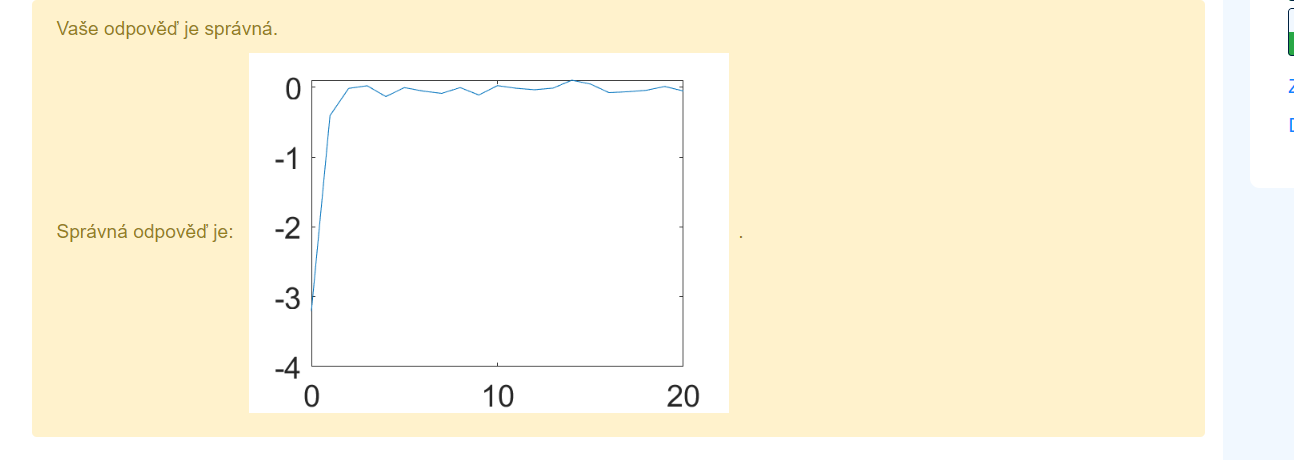

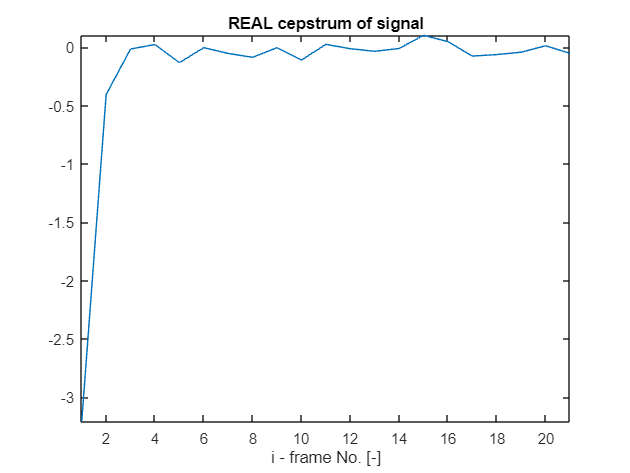

x = loadbin('frame-034.bin');
w = hamming(length(x));
x = x.*w;

wlen=512;
channels =1;
cp=16;
wstep=wlen/2;
p=16;

cr=rceps(x);

figure;
plot(cr(1:21)); axis tight;
title('REAL cepstrum of signal')

xlabel('i - frame No. [-]')

#### # 2 

Určete zkreslení delšího signálu [**SA016S01.CSX**](http://noel.feld.cvut.cz/vyu/b2m31dsp/sigtest/SA016S01.CSX) na bázi **kepstrální vzdálenosti a LPC KEPSTRA**, jestliže referenční nezkreslený signál je [**SA016S01.CS0**](http://noel.feld.cvut.cz/vyu/b2m31dsp/sigtest/SA016S01.CS0). Oba signály jsou uloženy jako binární soubory bez hlavičky, pro načtení do MATLABu použijte funkci *loadbin*. Počítejte LPC kepstrum po segmentech délky *wlen=512* s 50% překryvem a uvažujte implicitní váhování každého segmentu Hammingovým oknem. Řád LPC volte *p=16*, počet kepstrálních koeficentů (bez c[0]) volte *cp=20* a **vzdálenost počítejte na bázi Euklidovské vzdálenosti včetně nultého koeficientu c[0]**, tj. z koeficientů  **c[0]-c[20]**.

Pro výpočet vzdálenosti použijte funkci [**cde.m**](http://noel.feld.cvut.cz/vyu/b2m31dsp/m/cde.m) (POZN. Funkci je třeba stáhnout do aktuálního adresáře!!).

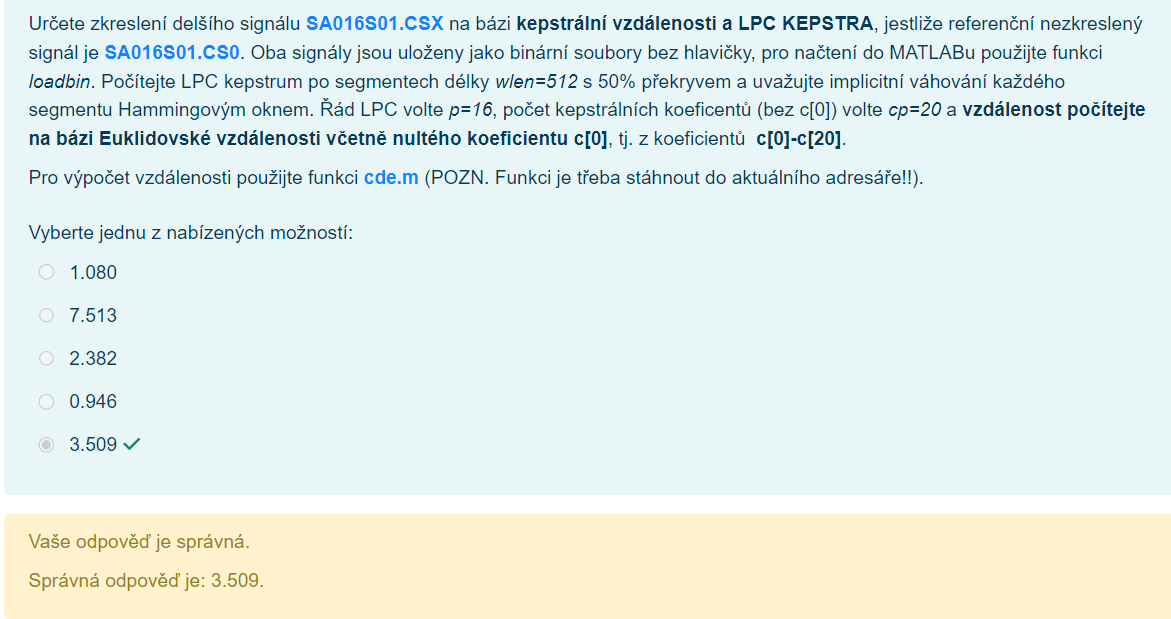

% Load the binary signals using loadbin function
refSignal = loadbin('SA016S01.CS0');

99792 samples were read!


distSignal = loadbin('SA016S01.CSX');

99792 samples were read!



% Define parameters
%fs = 16000;         % Sampling frequency (assumed)
wlen = 512;         % Frame length
wstep = wlen / 2;   % 50% overlap
p = 16;             % LPC order
cp = 20;            % Number of cepstral coefficients (c[0] to c[20])

% Use a Hamming window for each segment
window = hamming(wlen);

% Compute LPC cepstrum for both signals
lpcCepstraRef = vaceps(refSignal, 1, p, cp, wlen, wstep, window);
lpcCepstraDist = vaceps(distSignal, 1, p, cp, wlen, wstep, window);

% Compute Euclidean cepstral distance for each frame and average
numFrames = size(lpcCepstraRef, 1);
distances = zeros(numFrames, 1);
for i = 1:numFrames
    c1 = lpcCepstraRef(i, :);
    c2 = lpcCepstraDist(i, :);
    distances(i) = cde(c1, c2);
end

% Average distance
avgDistance = mean(distances);

% Display the result
disp(['Average Euclidean cepstral distance: ', num2str(avgDistance)]);

Average Euclidean cepstral distance: 3.5093


#### # 3  

Spočítejte **vyhlazený odhad vzájemné spektrální výkonové hustoty (CPSD)** Welchovou metodou pro signály **x** a **y** uložené v mat-souboru [**sig_xy_04.mat**](http://noel.feld.cvut.cz/vyu/b2m31dsp/sigtest/sig_xy_04.mat) (pro načtení do MATLABu použijte "*load sig_xy_04.mat*"). Signály jsou vzorkované kmitočtem fs = 16 kHz a pro výpočet volte následující parametry:

- délku krátkodobého segmentu volte *1024 vzorků*,

- krátkodobé segmenty váhujte *Hammingovým oknem*,

- segmentujte s *50% překryvem*,

- *počet bodů FFT* volte stejný, jako je délka segmentu,

- počítejte s implicitním *jednostranným odhadem CPSD* reálných signálů.

Určete, který z následujících obrázků je požadovaným odhadem **fáze CPSD v radiánech**!

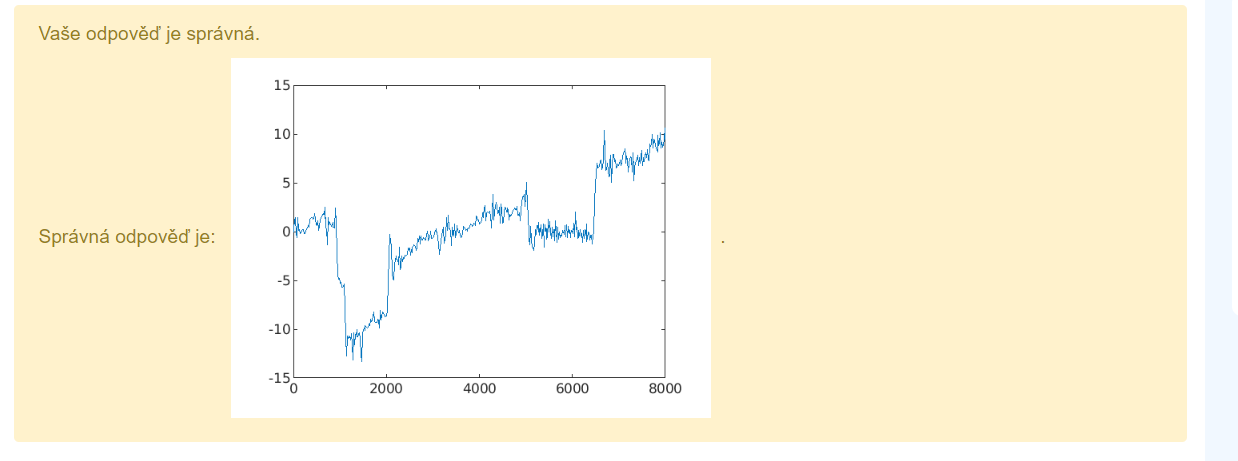

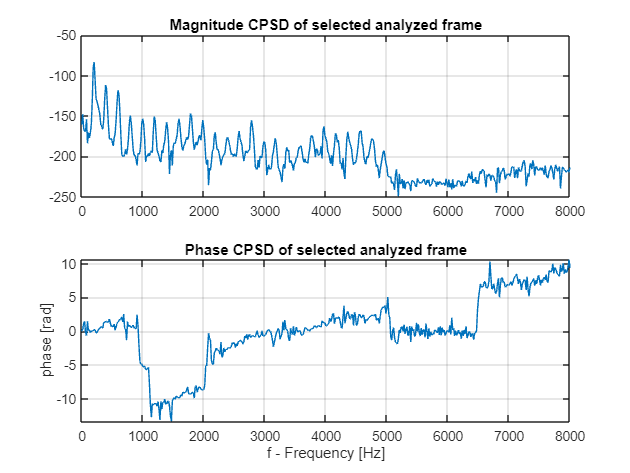

clear;clc;
load sig_xy_04.mat;

wlen = 1024;
% fs = 16kHz načteno z sig_xy_04.mat

[Pxy, FF] = cpsd(x, y, hamming(wlen), wlen/2, wlen, fs);

Pxydb = 10*log10(abs(Pxy));

figure;
subplot(211)
plot(FF,20*log10(abs(Pxy)));
title('Magnitude CPSD of selected analyzed frame');
grid
subplot(212)
plot(FF,unwrap(angle(Pxy)))
title('Phase CPSD of selected analyzed frame');
xlabel('f - Frequency [Hz]')
ylabel('phase [rad]')
grid

#### # 4 

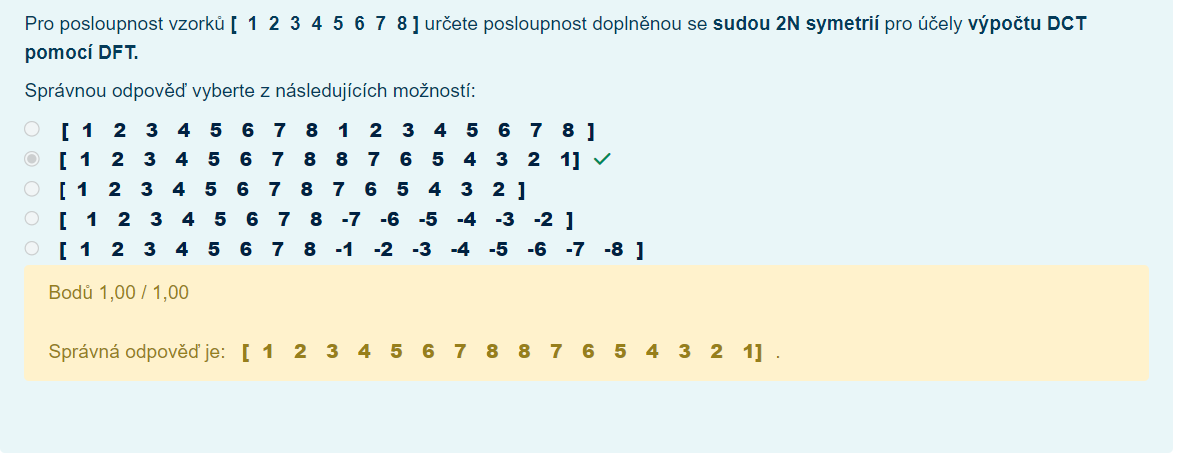

clear; clc;
x = [1 2 3 4 5 6 7 8]; % Zadaná posloupnost

% Určení délky původní posloupnosti
N = length(x);

% Doplnění posloupnosti se sudou 2N symetrií
x_sym = [x fliplr(x)]; % Symetrické doplnění

% Zobrazí původní a doplněnou posloupnost
disp('Původní posloupnost:');

Původní posloupnost:


disp(x);

     1     2     3     4     5     6     7     8



disp('Doplněná posloupnost se sudou 2N symetrií:');

Doplněná posloupnost se sudou 2N symetrií:


disp(x_sym);

     1     2     3     4     5     6     7     8     8     7     6     5     4     3     2     1



# # 5 NEMÁM SPRÁVNĚ

Určete **EUKLIDOVSKOU KEPSTRÁLNÍ VZDÁLENOST** na bázi **reálného** **KEPSTRA** mezi dvěma signály [**frame-001.bin**](http://noel.feld.cvut.cz/vyu/b2m31dsp/sigtest/frame-001.bin) a [**frame-012.bin**](http://noel.feld.cvut.cz/vyu/b2m31dsp/sigtest/frame-012.bin) (oba signály jsou uloženy jako binární soubory bez hlavičky, pro načtení do MATLABu použijte funkci *loadbin*). Počítejte reálné kepstrum, signály **váhujte Hammingovým oknem** příslušné délky. Vzdálenost počítejte z **prvních 12 koeficientů bez nultého koeficientu c[0]**, tj. z koeficientů **c[1]-c[12]**.

Pro výpočet vzdálenosti použijte funkci [**cde.m**](http://noel.feld.cvut.cz/vyu/b2m31dsp/m/cde.m) (POZN. Funkci je třeba stáhnout do aktuálního adresáře!!).

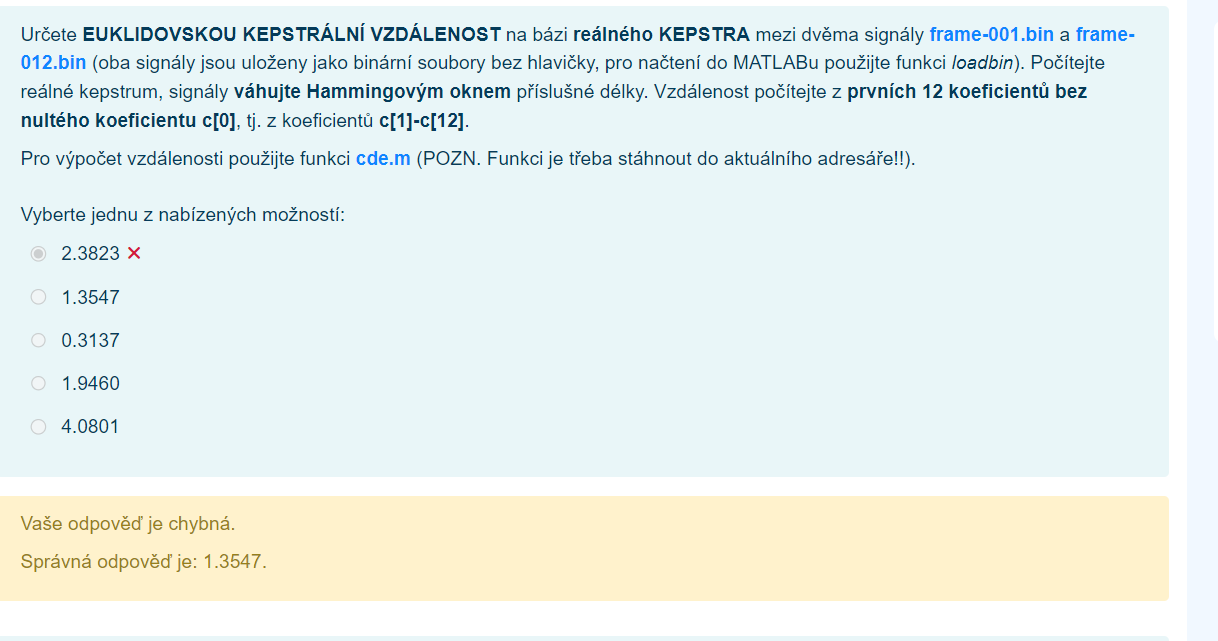

% Load the binary signals using loadbin function
signal1 = loadbin('frame-001.bin');

512 samples were read!


signal2 = loadbin('frame-012.bin');

512 samples were read!


% Definice délky Hammingova okna
delka_okna = length(signal1);

% Výpočet reálného kepstra s použitím Hammingova okna
cepstrum1 = vrceps(signal1 .* hamming(delka_okna));
cepstrum2 = vrceps(signal2 .* hamming(delka_okna));

% Vyberte prvních 13 koeficientů
cepstrum1 = cepstrum1(2:13);
cepstrum2 = cepstrum2(2:13);

% Výpočet euklidovské vzdálenosti
vzdalenost = cde(cepstrum1, cepstrum2);
disp(vzdalenost)

    1.8406



#### # 6  

Komprimuje signál [**frame-010.bin**](http://noel.feld.cvut.cz/vyu/b2m31dsp/sigtest/frame-010.bin) na bázi kosinové transformace (použijte funkce *dct* a *idct* definované v MATLABu). Pro danou kompresi (aproximaci) použijte prvních **50 komponent DCT spektra**. Signál je uložen jako binární soubor bez hlavičky, pro načtení do MATLABu použijte funkci *loadbin*. Původní a dekomprinovaný signál si pro kontrolu ilustrativně zobrazte.

Spočítejte výkony původního i komprimovaného signálu a určete jaké procento výkonu původního signálu je zahrnuto v signálu komprimovaném.

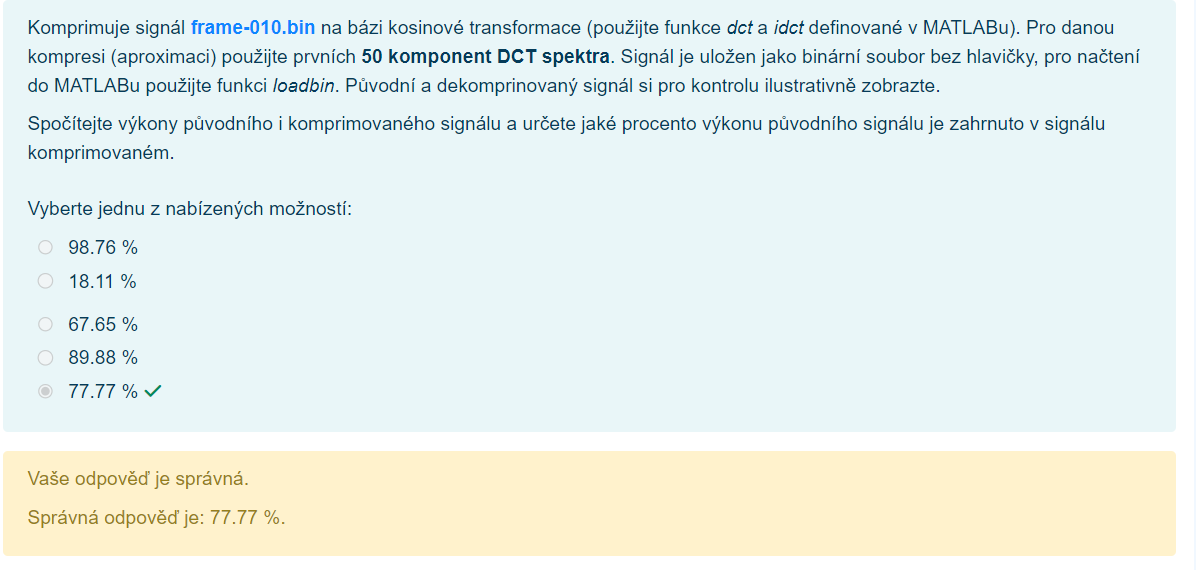

clc;clear;
signal = loadbin('frame-010.bin'); % Předpokládá se funkce loadbin pro načtení dat

512 samples were read!


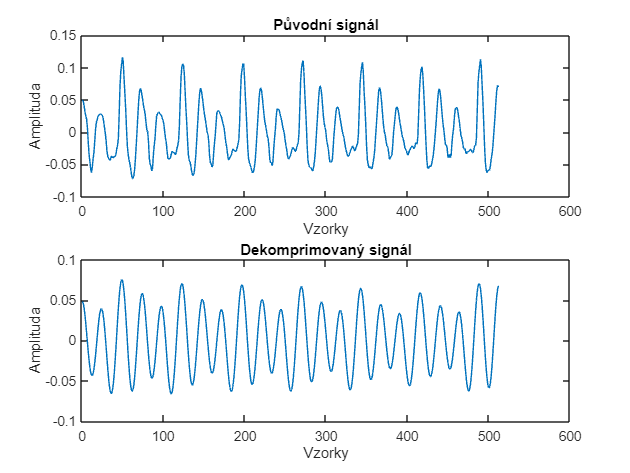


% Počet vzorků v signálu
N = length(signal);

% Výpočet DCT spektra
dctSignal = dct(signal);

% Ponechání pouze prvních 50 komponent DCT spektra
dctCompressed = zeros(size(dctSignal));
dctCompressed(1:50) = dctSignal(1:50);

% Dekomprese pomocí IDCT
reconstructedSignal = idct(dctCompressed);

% Vizualizace původního a dekomprimovaného signálu
figure;
subplot(2,1,1);
plot(signal);
title('Původní signál');
xlabel('Vzorky');
ylabel('Amplituda');

subplot(2,1,2);
plot(reconstructedSignal);
title('Dekomprimovaný signál');
xlabel('Vzorky');
ylabel('Amplituda');


% Výpočet výkonů signálů
powerOriginal = sum(signal.^2) / N;
powerReconstructed = sum(reconstructedSignal.^2) / N;

% Procentuální zastoupení výkonu v komprimovaném signálu
percentagePower = (powerReconstructed / powerOriginal) * 100;

% Zobrazení výsledků
disp(['Výkon původního signálu: ', num2str(powerOriginal)]);

Výkon původního signálu: 0.0019002


disp(['Výkon dekomprimovaného signálu: ', num2str(powerReconstructed)]);

Výkon dekomprimovaného signálu: 0.0014777


disp(['Procento výkonu původního signálu v komprimovaném signálu: ', num2str(percentagePower), '%']);

Procento výkonu původního signálu v komprimovaném signálu: 77.766%


#### # 7  

Jaký je **odstup signálu od šumu (SNR)** v případě sečtení užitečného signálu [**SA010S01.CS0**](http://noel.feld.cvut.cz/vyu/b2m31dsp/sigtest/SA010S01.CS0) a zeslabeného šumu [**nc0.bin**](http://noel.feld.cvut.cz/vyu/b2m31dsp/sigtest/nc0.bin), tj. konkrétně vynásobeného po načtení konstantou *scale = 0.5* ? Oba signály jsou uloženy jako binární soubory bez hlavičky, pro načtení do MATLABu použijte funkci *loadbin*.

Vypočítané SNR v dB uveďte s přesností na 2 desetinná čísla

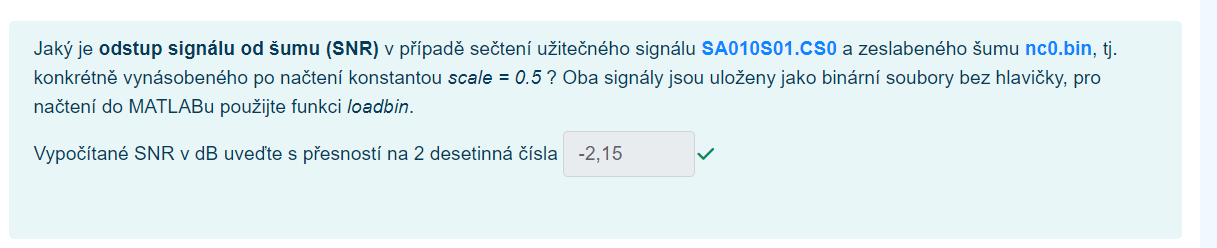

clc;clear

% Load the useful signal and noise
sig = loadbin('SA010S01.CS0');

77000 samples were read!


noise = loadbin('nc0.bin');

100000 samples were read!


% Ensure the noise array is not longer than the signal array
if length(noise) > length(sig)
    noise = noise(1:length(sig));
elseif length(noise) < length(sig)
    sig = sig(1:length(noise));  % Truncate signal to match noise length if needed
end

% Scale the noise
scale = 0.5;
scaledNoise = scale * noise;

% Create the noisy signal
noisySignal = sig + scaledNoise;

% Calculate power of the useful signal and the noise
powerSig = mean(sig.^2);
powerNoise = mean(scaledNoise.^2);

% Compute SNR
SNR = 10 * log10(powerSig / powerNoise);

% Display the SNR
disp(['The Signal-to-Noise Ratio (SNR) is: ', num2str(SNR), ' dB']);

The Signal-to-Noise Ratio (SNR) is: -2.1519 dB


#### # 8  

Pro signály **sig1** a **sig2** vzorkované kmitočtem *fs = 8 kHz* a uložené v mat-souboru [**sigs_2chan_08.mat**](http://noel.feld.cvut.cz/vyu/b2m31dsp/sigtest/sigs_2chan_08.mat) (pro načtení do MATLABu použijte "*load sigs_2chan_08.mat*") vypočtěte **koherenční funkci,** konkrétně **MSC (Magnitude Square Coherence)**, přičemž pro výpočet volte následující parametry:

- délka krátkodobého segmentu - *64 ms*,

- váhování - *Hammingovo okno* odpovídající délky,

- segmentace - s *50% překryvem*,

- řád FFT - stejný, jako je *délka krátkodobého segmentu*.

Určete **průměrnou koherenci** (tj. průměrnou hodnotu vypočítané MSC). Výsledek uveďte s minimální přesností na 3 platné cifry.

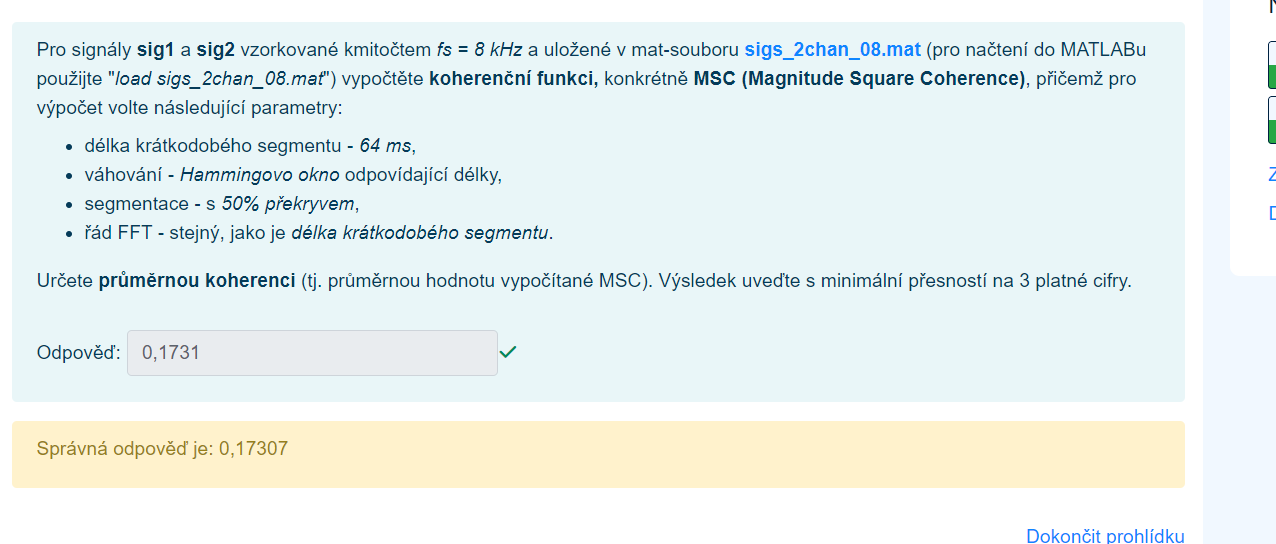

clc;clear;
% Určete průměrnou koherenci
load sigs_2chan_08.mat;
fs=8000; 
wlen = 0.064*fs;
 
[Cxy, FF] = mscohere(sig1, sig2, hamming(wlen), wlen/2, wlen, fs);
 
mean(Cxy)

ans = 0.1731